# РГР №2 -  8-PSK

## студента: Красницького Микити

Початкові умови

clear all
close all
var = 9;
Br = 300 * var; 

Битрейт в 27000 означает, что за одну секунду передается 27к кодированных отчетов, а значит частота семплирования равна битрейду (столько отчетов будет взято в одну секунду). Частота должна быть больше(?)

Fs = 16*Br;%%???

Количесвто бит передаваемых звездой созвездия обозначу m. Поскольку 8-PSK, то 2^3 = 8. Передается 3 бита. Создаем соответствующуюю таблицу из точек созвездия.

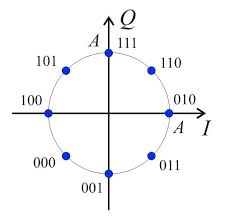

m = 3;
IQ_table = [1, -1*i, -1, 1*i;
            0.707+0.707*1i, 0.707-0.707*1i, -0.707-0.707*1i, -0.707+0.707*1i;];

Создаем искусственные данные. Случайный битовый поток из Nbit битов. Эти биты передают 128 символов, т.е 128 звезд из созвездия. Зная кол-во бит передаваемых в секунду (Br) и кол-во бит, составляющих символ найдем Symbol rate (Sr)

Sr = Br/m;
Ns = 64;
Nbit = m*Ns;
data = randi([0, 1], 1, Nbit); % Random bit-flow 0011010010

Делим поток бит на m частей и составляем из них m строк, длинной в Ns, где каждому столбцу соответствует один символ, т.е. одна комбинация m-битов

data = reshape(data, m, Ns);
data = bi2de(data') + 1; % Transform every binary col to decimal value (1 - m+1)
dataIQ = IQ_table(data);

Вывожу звезды (символы) и единичный круг.

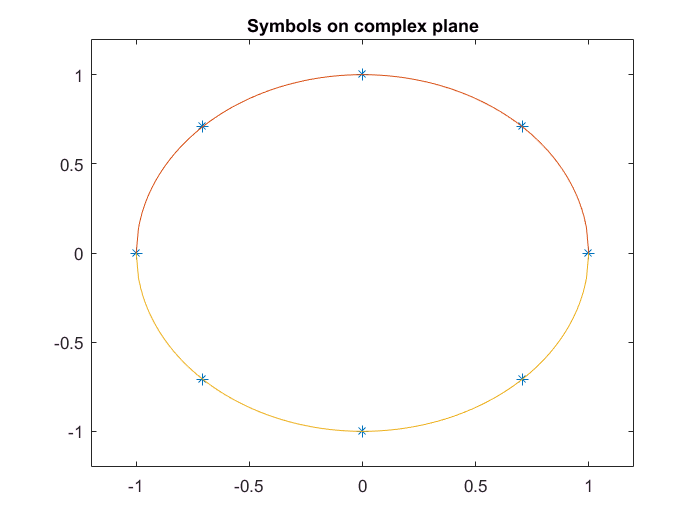

figure         
plot(real(dataIQ), imag(dataIQ), '*'); % Print by *
hold on
tt = [-1:1/100:1];
plot(tt, sqrt(1-tt.^2));
plot(tt, -sqrt(1-tt.^2));
axis([-1.2 1.2 -1.2 1.2]);
title('Symbols on complex plane');
hold off

Отображу I и Q сигналы

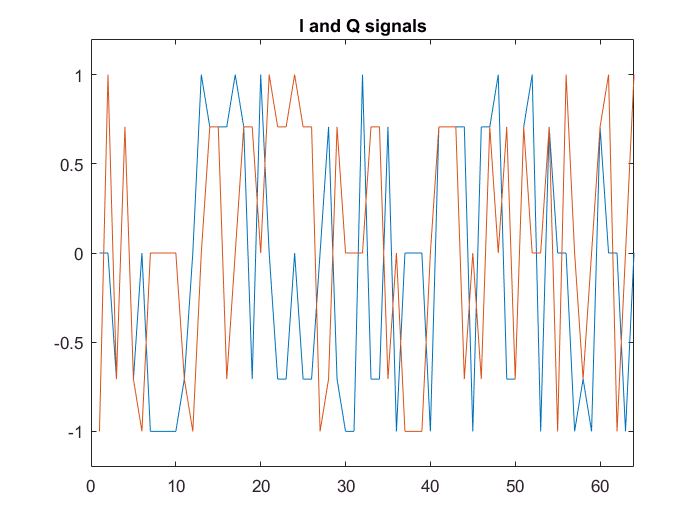

I = real(dataIQ);
Q = imag(dataIQ);
figure
plot(I);
hold on
plot(Q);
hold off
axis([0 Ns -1.2 1.2]);
title('I and Q signals');

Сигналы нужно растянуть во времени. Пускай будет введена величина sampels per symbol (sps), которая укажет сколько тактов длится каждый символ

sps = Fs/Sr;
N = Ns*sps; % Number of samples 256
I = I';
Q = Q';
I = repmat(I, sps, 1); 
I = reshape(I, 1, N);

Q = repmat(Q, sps, 1); 
Q = reshape(Q, 1, N);

Отображение растянутых во времени I и Q

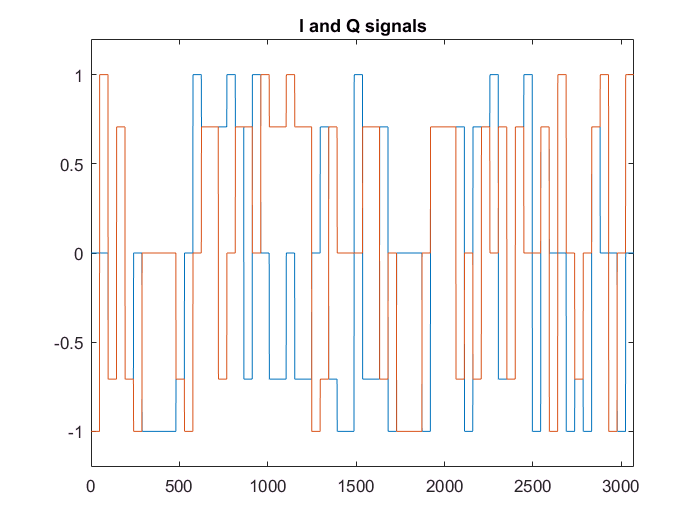

figure
plot(I);
hold on
plot(Q);
hold off
axis([0 N -1.2 1.2]);
title('I and Q signals');

Формирую сигнал и показываю спектр искодного сигнала.

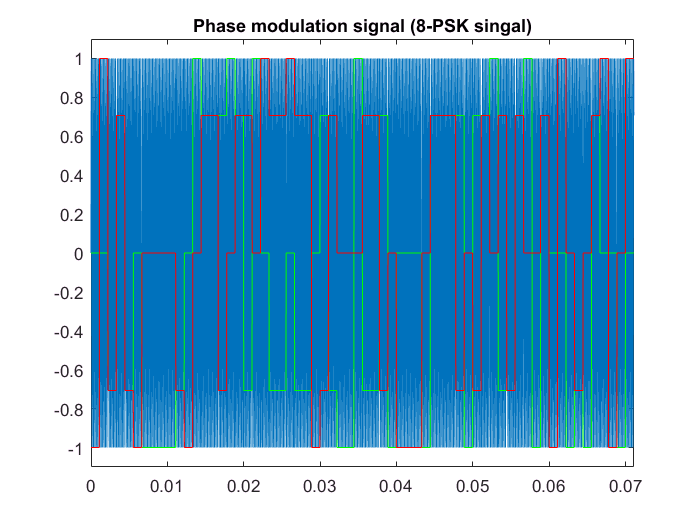

t = [0:N-1]/Fs; % Time
f0 = Fs/8; % Carryir frequency
%%%%%%%%%%%%%%%%%%%%%%%%%% Signal %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
s = I.*cos(2*pi*f0*t) - Q.*sin(2*pi*f0*t);
plot(t, s);
hold on
plot(t, I, 'g');
plot(t, Q, 'r');
axis([0 N/Fs -1.1 1.1]);
hold off
title('Phase modulation signal (8-PSK singal)'); % that contains data information

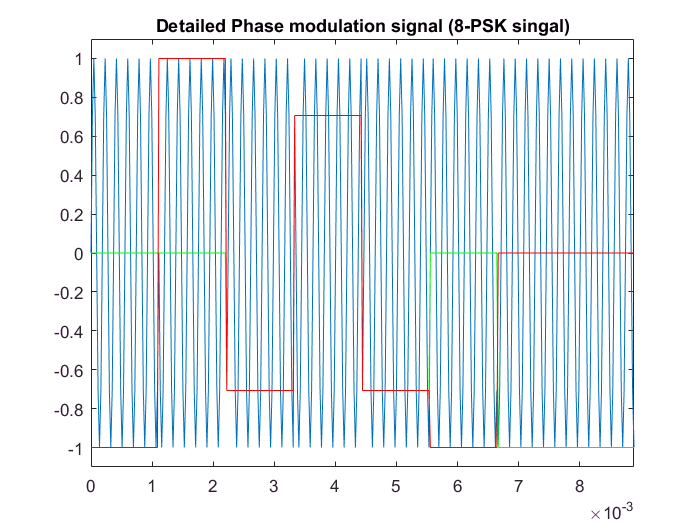

figure
plot(t, s);
hold on
plot(t, I, 'g');
plot(t, Q, 'r');
axis([0 N/Fs/8 -1.1 1.1]);
hold off
title('Detailed Phase modulation signal (8-PSK singal)');

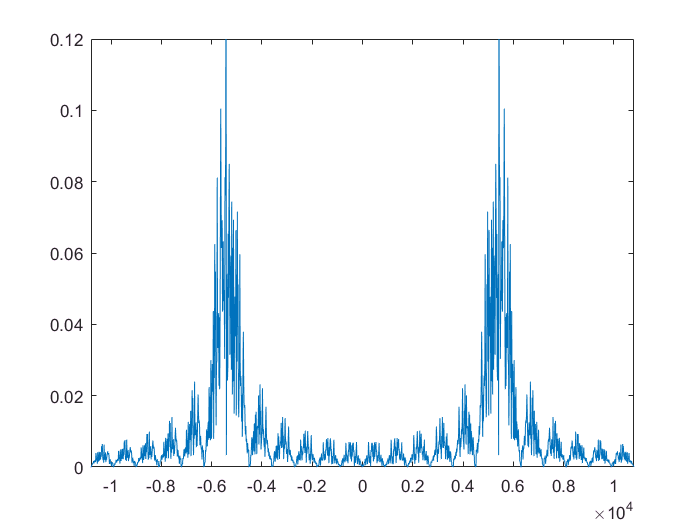

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Spectrum %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S = fftshift(fft(s)) / N; % Find spectrum and shift it right part to normal place
ff = [-N/2: N/2 - 1] * Fs/N;
plot(ff, abs(S));
axis([-2*f0 2*f0 0 0.12]);

Оценивая главный лепесток спектра по уровню ноль получаем ширину спектра примерно в Br = 2700 Гц

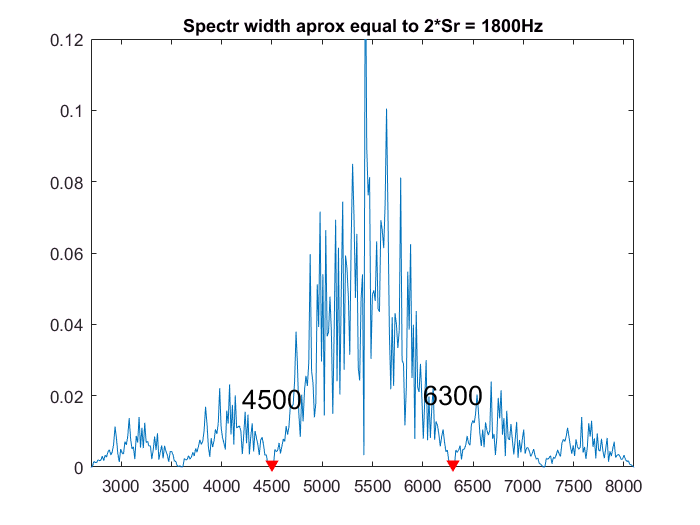

figure
plot(ff, abs(S));
hold on
F = [f0-Sr f0+Sr];
FreqToDot = round( ((2*F)/Fs+1)*N/2 );
FreqDot = ff( FreqToDot );
plot(F, abs(S(FreqToDot)),'rv', 'MarkerFaceColor', 'r');
celltext = cellstr(num2str(F'));
text(F - 300, abs(S(FreqToDot) + 0.02), celltext, 'FontSize', 16);
axis([(f0 - 3*Sr) (f0 + 3*Sr) 0 0.12]);
title('Spectr width aprox equal to 2*Sr = 1800Hz');
hold off

## Применение фильтра приподнятого косинуса

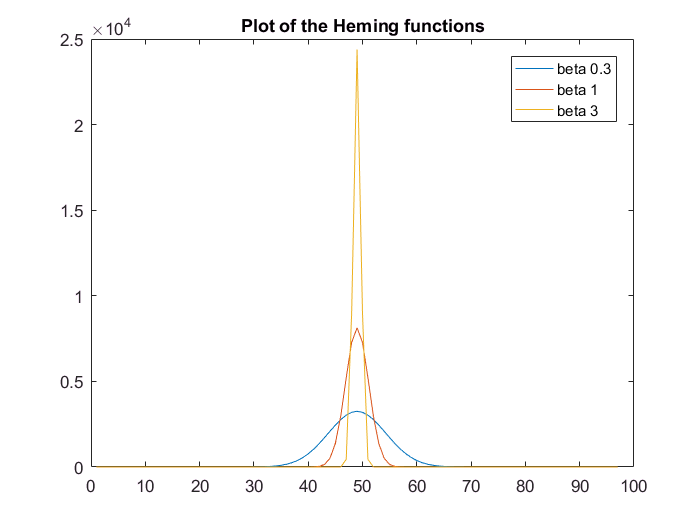

beta = [0.4 1 3];
K = 3;
tau = [-K/Br:1/Fs:K/Br];
g1 = beta(1)* Br*sqrt(2*pi/log(2))*exp(-2*pi*pi*beta(1)*beta(1)*tau.*tau*Br*Br/log(2));
g2 = beta(2)* Br*sqrt(2*pi/log(2))*exp(-2*pi*pi*beta(2)*beta(2)*tau.*tau*Br*Br/log(2));
g3 = beta(3)* Br*sqrt(2*pi/log(2))*exp(-2*pi*pi*beta(3)*beta(3)*tau.*tau*Br*Br/log(2));
figure
plot(g1);
hold on
plot(g2);
plot(g3);
%axis([150 450 0 8500]);
title('Plot of the Heming functions')
legend('beta 0.3','beta 1', 'beta 3')
hold off

Прохождение сигналов через фильтр эквивалентно свертке с его импульсной характеристикой

I_f = [conv(I, g1/Fs, 'same'); conv(I, g2/Fs, 'same'); conv(I, g3/Fs, 'same')];
Q_f = [conv(Q, g1/Fs, 'same'); conv(Q, g2/Fs, 'same'); conv(Q, g3/Fs, 'same')];
data_f1 = I_f(1,:) + 1i.*Q_f(1,:);
data_f2 = I_f(2,:) + 1i.*Q_f(2,:);
data_f3 = I_f(3,:) + 1i.*Q_f(3,:);
figure         
plot(real(dataIQ), imag(dataIQ), '*'); % Print by *
hold on
tt = [-1:1/100:1];
plot(tt, sqrt(1-tt.^2));
plot(tt, -sqrt(1-tt.^2));
axis([-1.2 1.2 -1.2 1.2]);
title('Symbols on complex plane');
hold off

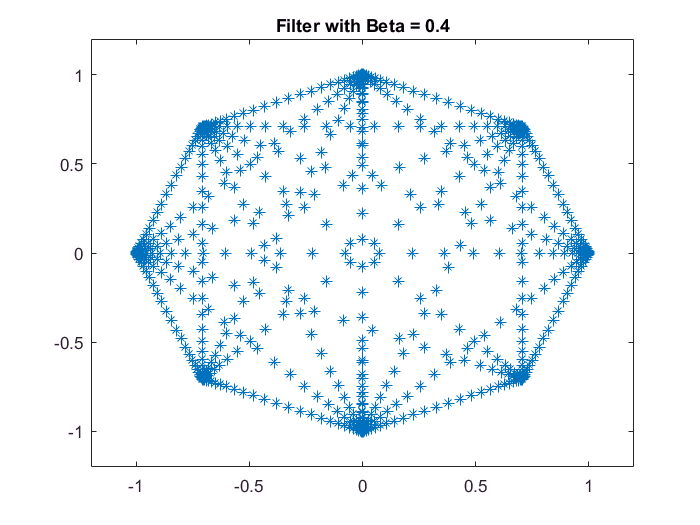

figure
plot(real(data_f1), imag(data_f1), '*'); % Print by *
axis([-1.2 1.2 -1.2 1.2]);
title('Filter with Beta = 0.4');

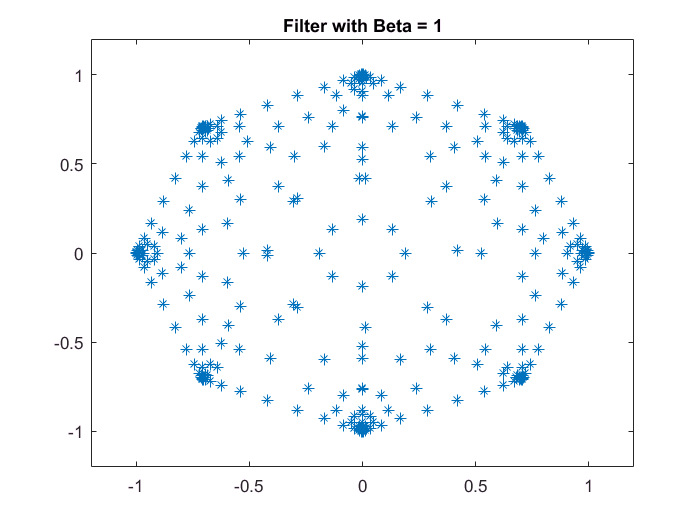

figure
plot(real(data_f2), imag(data_f2), '*'); % Print by *
axis([-1.2 1.2 -1.2 1.2]);
title('Filter with Beta = 1');

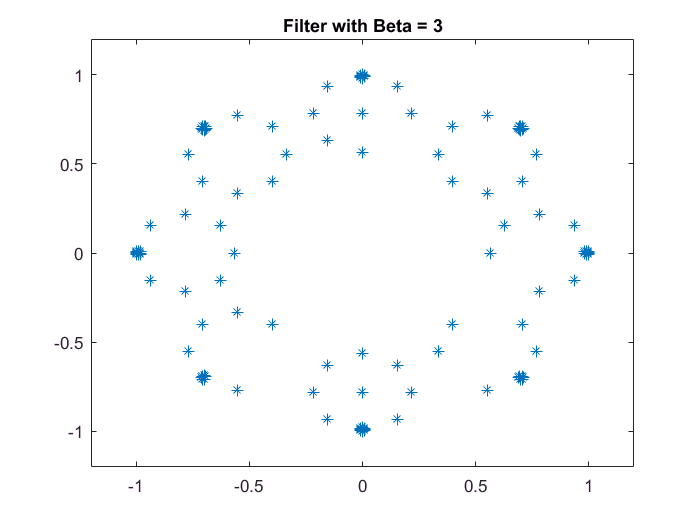

figure
plot(real(data_f3), imag(data_f3), '*'); % Print by *
axis([-1.2 1.2 -1.2 1.2]);
title('Filter with Beta = 3');


% Проверка правильности метода получения созвездий
% dataIQ = dataIQ';
% dataIQ = repmat(dataIQ, sps, 1); 
% dataIQ = reshape(dataIQ, 1, N);
% dataIQ_f = conv(dataIQ, g1/Fs, 'same');
% plot(real(dataIQ_f));
% plot(I_f(1,:));

## Спектры отфильтрованного сигнала через разные фильтры

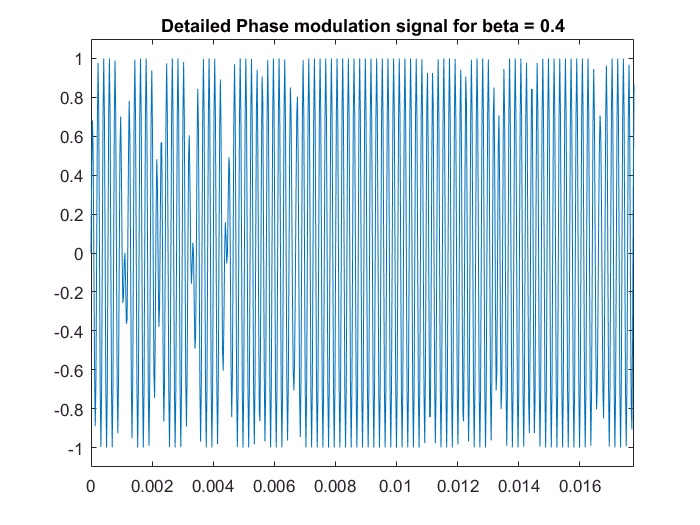

%%%%%%%%%%%%%%%%%%%%%%%%%% Signal %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
s1 = I_f(1,:).*cos(2*pi*f0.*t) - Q_f(1,:).*sin(2*pi*f0.*t);
s2 = I_f(2,:).*cos(2*pi*f0.*t) - Q_f(2,:).*sin(2*pi*f0.*t);
s3 = I_f(3,:).*cos(2*pi*f0.*t) - Q_f(3,:).*sin(2*pi*f0.*t);

figure
plot(t, s1);
title('Detailed Phase modulation signal for beta = 0.4');
axis([0 N/Fs/4 -1.1 1.1]);

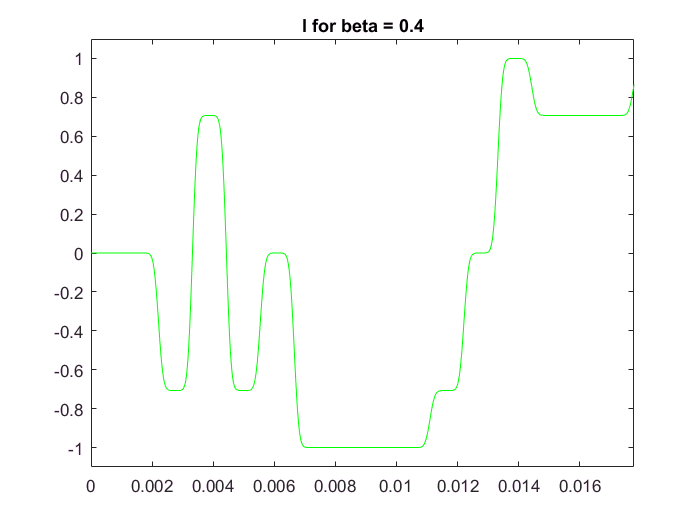


figure
plot(t, I_f(1,:), 'g');
title('I for beta = 0.4');
axis([0 N/Fs/4 -1.1 1.1]);

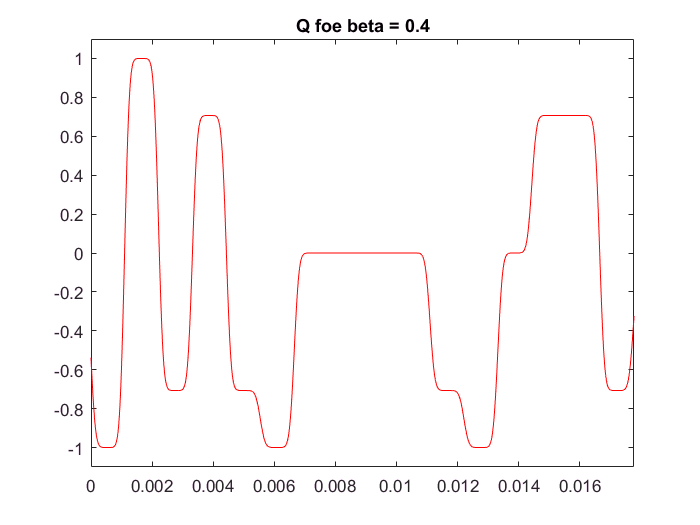


figure
plot(t, Q_f(1,:), 'r');
title('Q foe beta = 0.4');
axis([0 N/Fs/4 -1.1 1.1]);

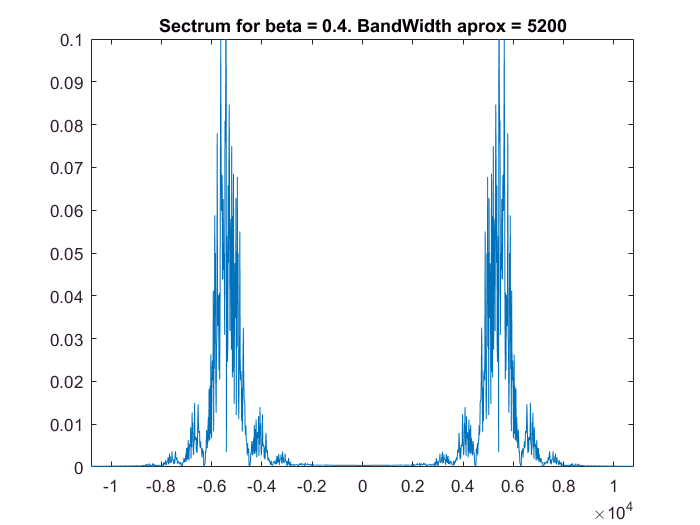


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Spectrum %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S1 = fftshift(fft(s1)) / N; % Find spectrum and shift it right part to normal place
S2 = fftshift(fft(s2)) / N;
S3 = fftshift(fft(s3)) / N;
ff = [-N/2: N/2 - 1] * Fs/N;
plot(ff, abs(S1));
axis([-2*f0 2*f0 0 0.1]);
title('Sectrum for beta = 0.4. BandWidth aprox = 1800');

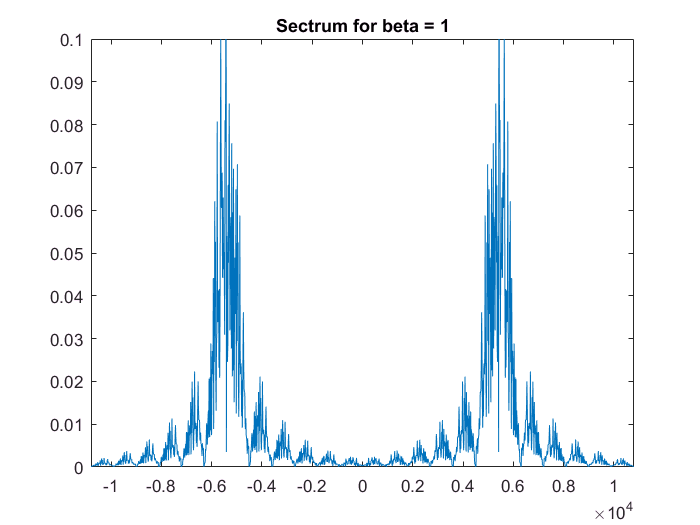

plot(ff, abs(S2));
axis([-2*f0 2*f0 0 0.1]);
title('Sectrum for beta = 1');

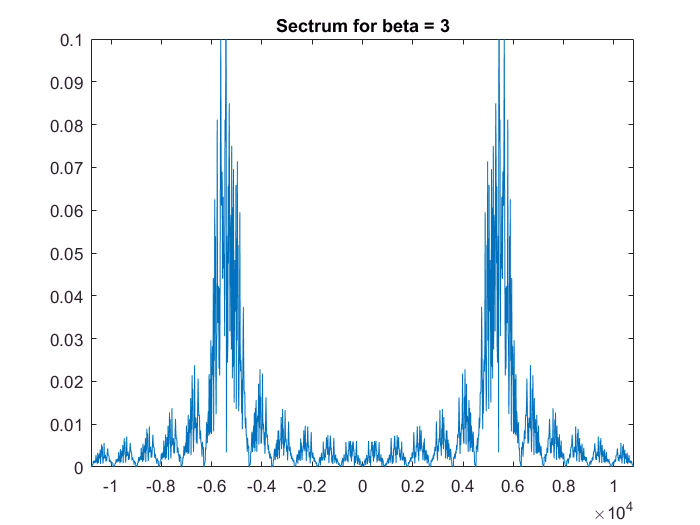

plot(ff, abs(S3));
axis([-2*f0 2*f0 0 0.1]);
title('Sectrum for beta = 3');

4 Пункт

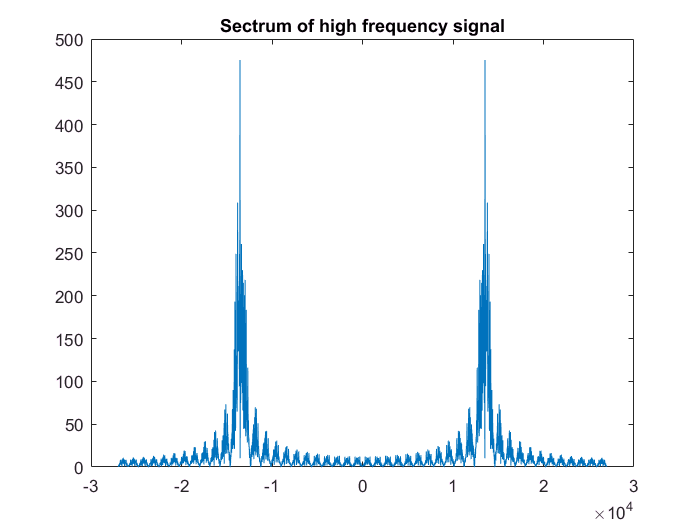

f0 = 1500*var;
Fs = 4*f0;
t = [0:N-1]/Fs;
s = I.*cos(2*pi*f0.*t) - Q.*sin(2*pi*f0.*t);
S = fftshift(fft(s));
ff = [-N/2: N/2 - 1] * Fs/N;
plot(ff, abs(S));
title('Sectrum of high frequency signal');

## Выводы

- Фазовая модуляция позволяет передавать пакет бит (3 бита в данном случае) одним фазовым скачком, который определяет звезду созвездия

- Использование окна оставляет неизменным главный лепесток и глушит боковые лепестки, чем с относительно малыми потерями может сузить диапазон используемых частот.

# РГР №3 - 16-QAM и 64-QAM

## студента: Красницького Микити

## 16-QAM

clear all
close all
var = 9;
Br = 100 * var; 
Fs = 16*Br;
F0 = Br/16;
m = 4;
sps = 1024;
Sr = 16;
Ns = 64;           % 225 symbols. Bitrate - 225*m = 900. TIME of transmittion 2 sec
          % 113 - sample rate. On one symbol 128 samples.
N = Ns*sps; % Number of samles. Ns/Sr - time that needed to transmitt one symbol
t = [0:N-1]/Fs; % Time
Nbit = Ns*m; % Count of bits, that we will crate randomly.
             % One symbol - combination of I and Q

Дата

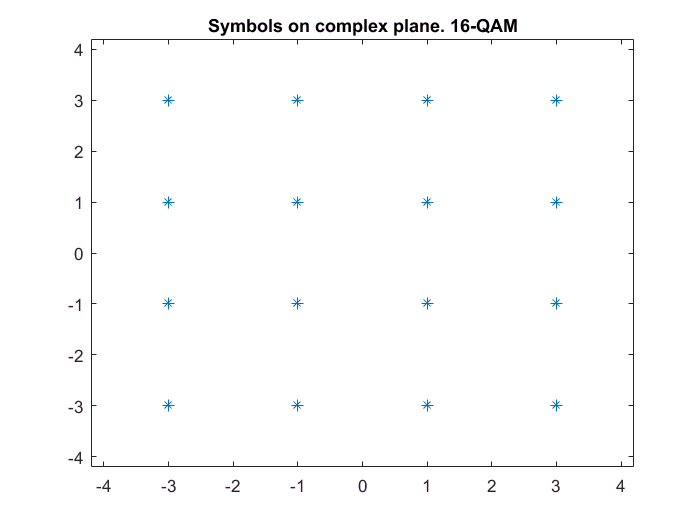

data = randi([0, 1], 1, Nbit); % Random bit-flow 0011010010
IQ_table = [-3+3*i, -1+3*i, 1+3*i, 3+3*i;
            -3+1*i, -1+1*i, 1+1*i, 3+1*i;
            -3-1*i, -1-1*i, 1-1*i, 3-1*i;
            -3-3*i, -1-3*i, 1-3*i, 3-3*i]; % Table for 4 bit on one symbol
data = reshape(data, m, Ns); 
data = bi2de(data') + 1; % Transform every binary row to decimal value
dataIQ = IQ_table(data); % Get matrix 1xNs of symbos 
                         %(that transmitted via pair bit flow)
figure         
%plot(real(dataIQ), imag(dataIQ), '*'); % Print by *
plot(real(dataIQ), imag(dataIQ), '*'); % Print by *
axis([-4.2 4.2 -4.2 4.2]);
title('Symbols on complex plane. 16-QAM');

Сигнал and Spectrum

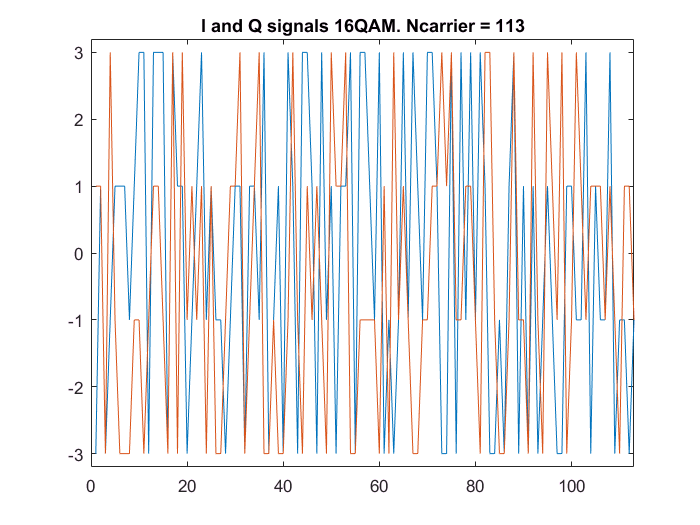

dataIQ_long = dataIQ';
dataIQ_long = repmat(dataIQ_long, sps, 1); % SPS times make copy to next row
                                 % Get matrix sps x Ns
dataIQ_long = reshape(dataIQ_long, 1, N);  % Make one row by reading colloms
I = real(dataIQ_long);
Q = imag(dataIQ_long);
%%%%%%%%%%%%%%%%%%%%%%%%%% Signal %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure

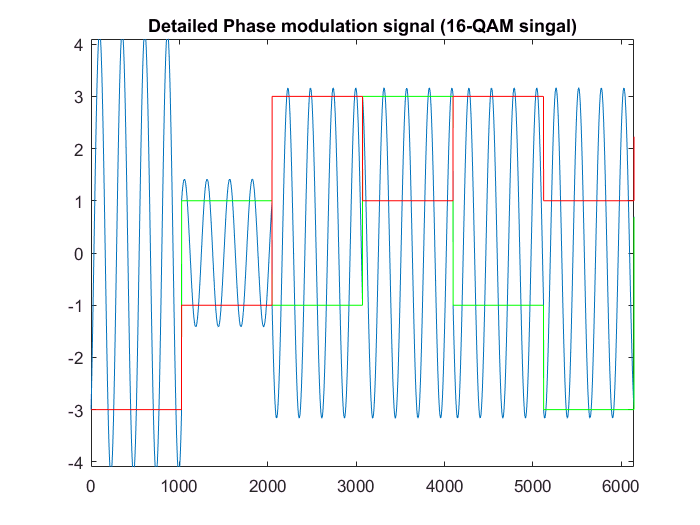

s = I.*cos(2*pi*F0*t) - Q.*sin(2*pi*F0*t);
figure
plot(s);
hold on
plot(I, 'g');
plot(Q, 'r');
axis([0 sps*6 -4.1 4.1]);
hold off
title('Detailed Phase modulation signal (16-QAM singal)');

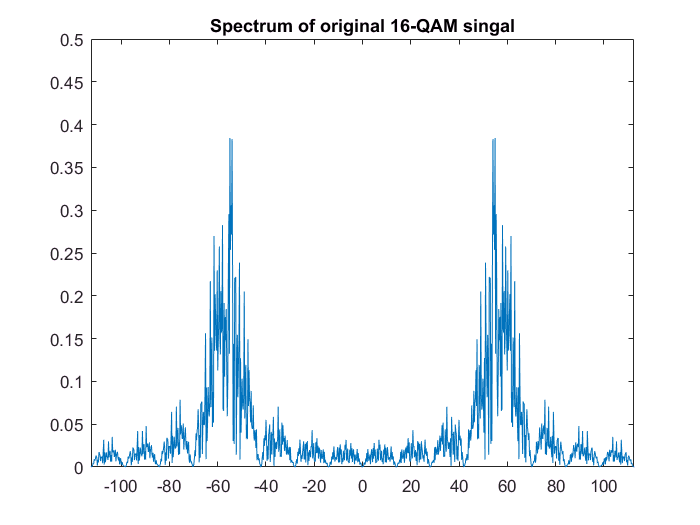

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Spectrum %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S = fftshift(fft(s))/N; % Find spectrum and shift it right part to normal place
ff = [-N/2: N/2 - 1] * Fs/N;
plot(ff, abs(S));
axis([-2*F0 2*F0 0 0.5]);
title('Spectrum of original 16-QAM singal');

Ширина спектра

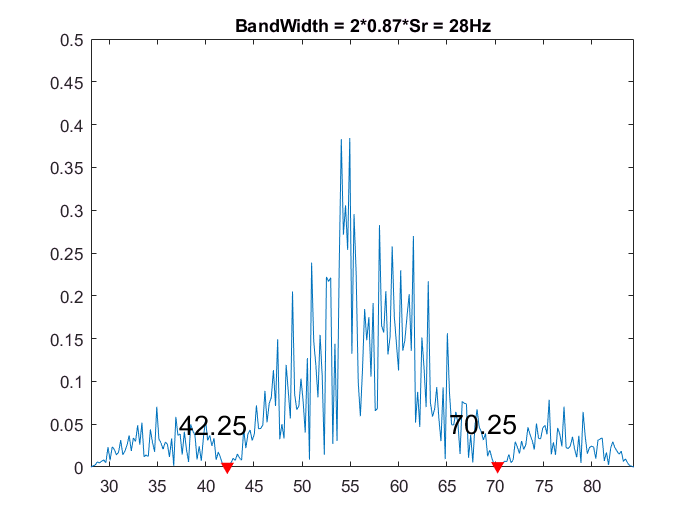

plot(ff, abs(S));
hold on
F = [F0 - 14, F0 + 14];
FreqToDot = round( ((2*F)/Fs+1)*N/2 );
FreqDot = ff( FreqToDot );
plot(F, abs(S(FreqToDot)),'rv', 'MarkerFaceColor', 'r');
celltext = cellstr(num2str(F'));
text(F-5, abs(S(FreqToDot))+0.05, celltext, 'FontSize', 16);
axis([0.5*F0 1.5*F0 0 0.5]);
title('BandWidth = 2*0.87*Sr = 28Hz');
hold off

## Прохождение через фильтр

Добавим условие, что сигнал нам важен только в некоторые моменты времени. Всего в дате сейчас 64 символа. После последующего ряда операций между символами будет вставлено 1024 нуля. То есть только каждый 1025 отчет даты важен и несет информацию. Последующая фильтрация путем произвольного поведения в промежутках между символами будет уменьшать спектр, понижая уровень боковых лепестков, но значения символов на каждом 1025 отчете будут неизменны.

dataIQ = dataIQ';
dataIQ = [dataIQ; zeros(sps-1, Ns)]; %%%%%%%%%%%%%%%%%%%%%%%%% Filtraciya
%dataIQ = repmat(dataIQ,sps,1);
dataIQ = reshape(dataIQ, 1, N);  % M

В созвездии такой даты появится точка (0,0), а I и Q будут иметь вид коротких импульсов.

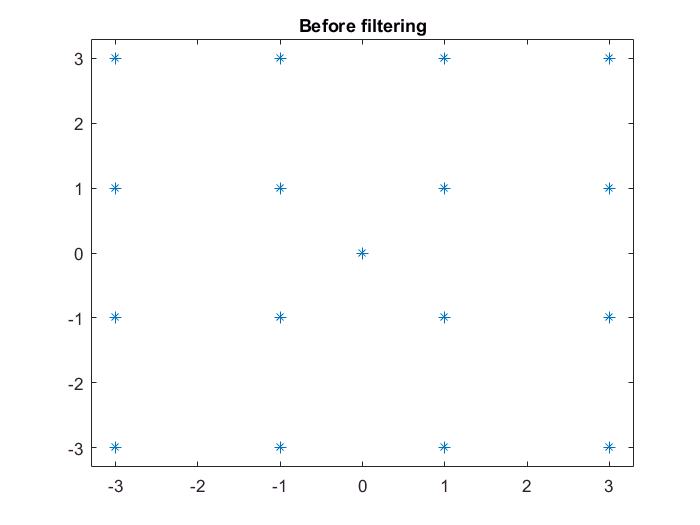

I = real(dataIQ);
Q = imag(dataIQ);
plot(I, Q, '*');
title('Before filtering');
axis([-3.3 3.3 -3.3 3.3]);

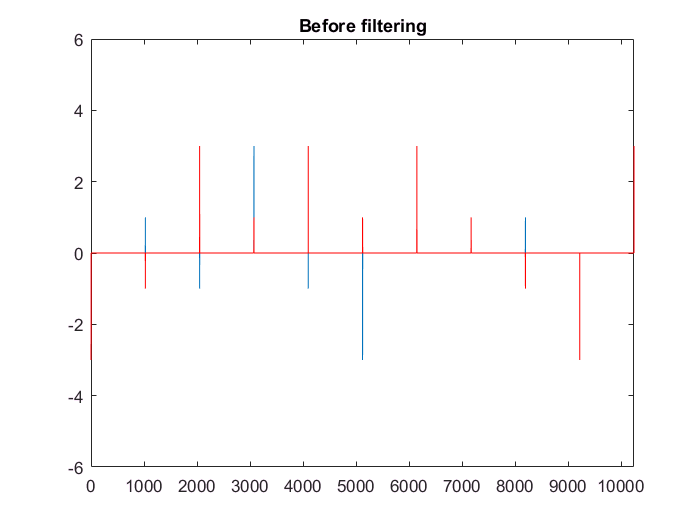

figure
plot(I);
hold on
plot(Q, 'r');
hold off
title('Before filtering');
axis([0 sps*10 -6 6]);

Создадим фильтр, импульсной характеристикой которого будет приподнятый косинус

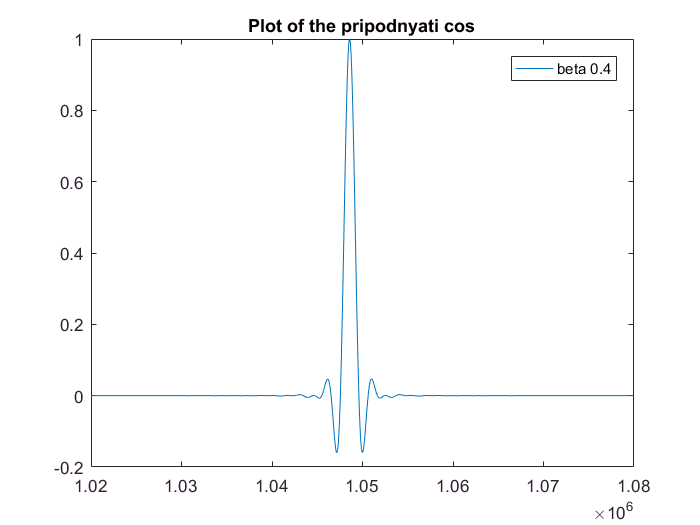

beta = 0.4;
span = 2048;
g = rcosdesign(beta, span, sps, 'normal'); % Create filter
g = g/sum(g);                              % Normalize
g = g * sps;                               % Return power loss from filled data with zeros
figure
plot(g);
title('Plot of the pripodnyati cos');
legend('beta 0.4');
axis([1.02e6 1.08e6 -0.2 1]);

Пропустим дату через фильтр (свертка)

dataIQ_f - filtered data IQ

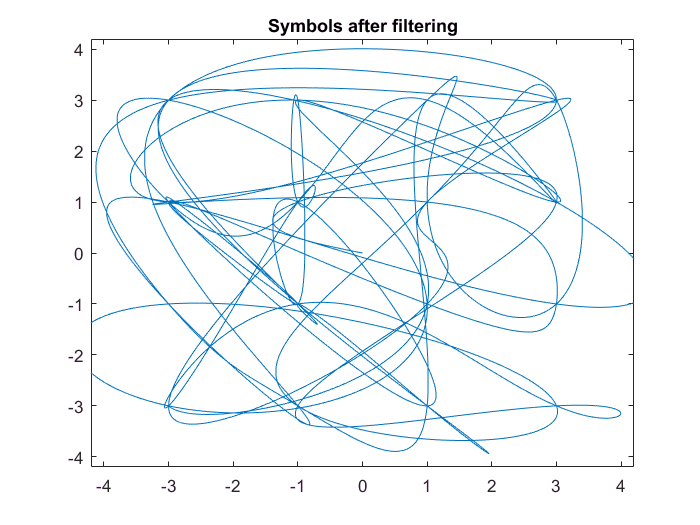

dataIQ_f = conv(dataIQ, g, 'same');
plot(real(dataIQ_f), imag(dataIQ_f));
title('Symbols after filtering');
axis([-4.2 4.2 -4.2 4.2]);

А теперь вместе с изображением прошедшего через фильтр сигнала звездочками покажу исходную дату. Каждый 1025 отчет должен совпадать и соответствовать одной из звезд созвездия. А как видно из предыдущего графика, звезд появилось гораздо больше.

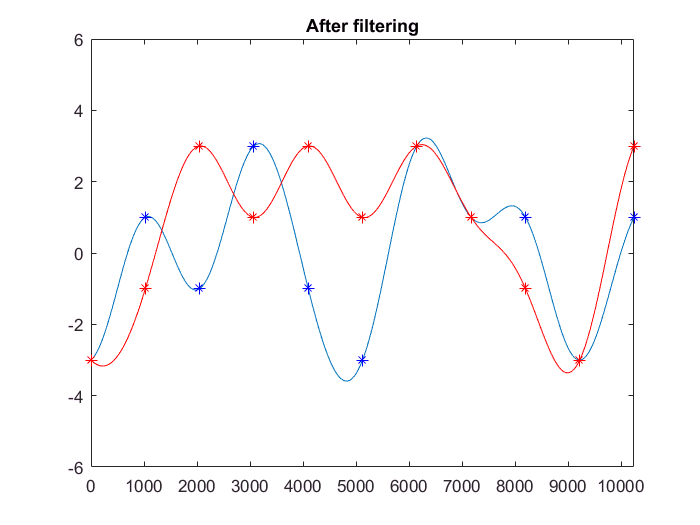

figure
plot(real(dataIQ_f));      % Filtering output I
hold on
plot(imag(dataIQ_f), 'r'); % Filtering output Q
plot([1:sps:Ns*sps],I(1:sps:end), 'b*'); % Every sps element of input I
plot([1:sps:Ns*sps],Q(1:sps:end), 'r*'); % Every sps element of input Q
hold off
title('After filtering');
axis([0 sps*10 -6 6]);

Для наглядности покажу созвездие из "символов", т.е. взяв каждый sps-тый отчет выходного из фильтра сигнала

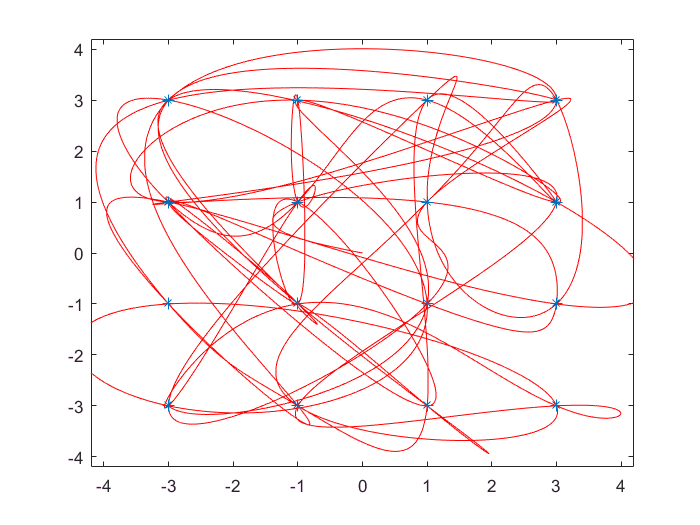

plot(real(dataIQ_f), imag(dataIQ_f), 'r');
hold on
plot(real(dataIQ_f(1:sps:end)), imag(dataIQ_f(1:sps:end)), '*');
hold off
axis([-4.2 4.2 -4.2 4.2]);

## Спектр фильрованного сигнала 16-QAM

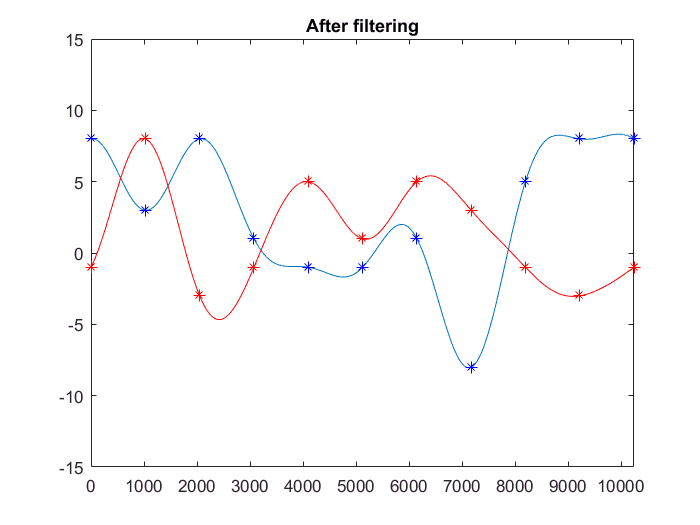

I = real(dataIQ_f);
Q = imag(dataIQ_f);
%%%%%%%%%%%%%%%%%%%%%%%%%% Signal %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure

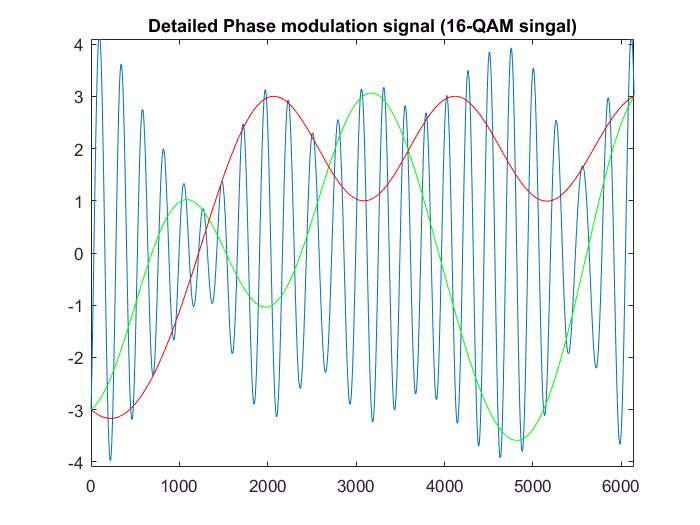

s = I.*cos(2*pi*F0*t) - Q.*sin(2*pi*F0*t);
figure
plot(s);
hold on
plot(I, 'g');
plot(Q, 'r');
axis([0 sps*6 -4.1 4.1]);
hold off
title('Detailed Phase modulation signal (16-QAM singal)');

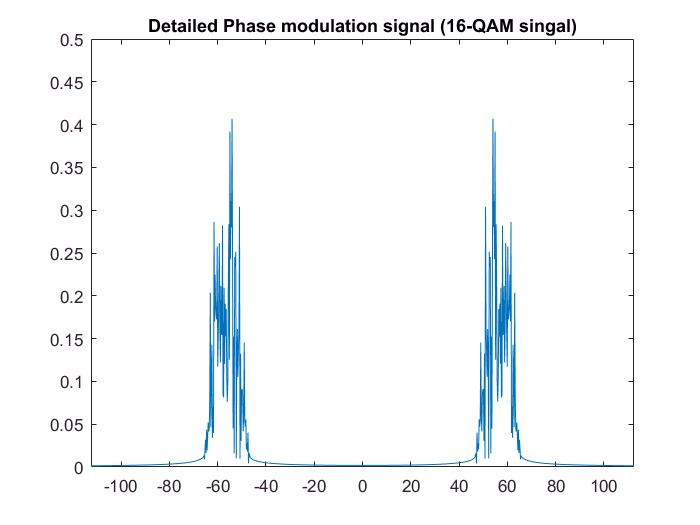

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Spectrum %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S = fftshift(fft(s))/N; % Find spectrum and shift it right part to normal place
ff = [-N/2: N/2 - 1] * Fs/N;
plot(ff, abs(S));
axis([-2*F0 2*F0 0 0.5]);
title('Detailed Phase modulation signal (16-QAM singal)');

Спектр фильтрованного сигнала

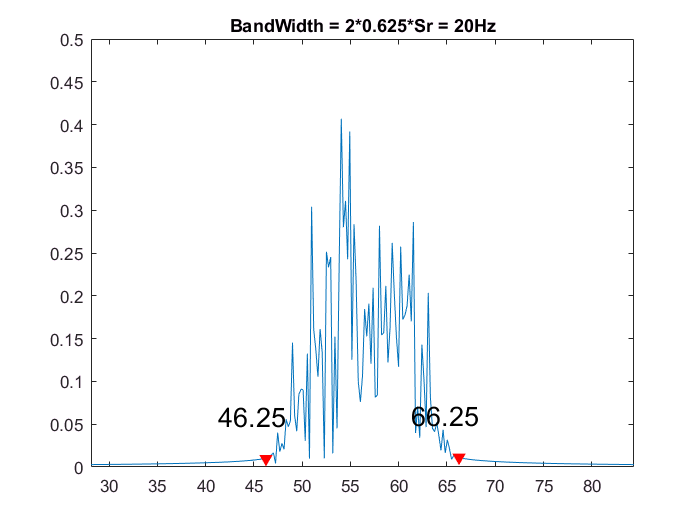

plot(ff, abs(S));
hold on
F = [F0 - 10, F0 + 10];
FreqToDot = round( ((2*F)/Fs+1)*N/2 );
FreqDot = ff( FreqToDot );
plot(F, abs(S(FreqToDot)),'rv', 'MarkerFaceColor', 'r');
celltext = cellstr(num2str(F'));
text(F-5, abs(S(FreqToDot))+0.05, celltext, 'FontSize', 16);
axis([0.5*F0 1.5*F0 0 0.5]);
title('BandWidth = 2*0.625*Sr = 20Hz');
hold off

## 64-QAM

Повторяю тоже самое для 64-QAM

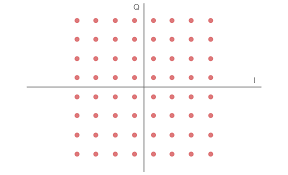

clear all
close all
var = 9;
Br = 100 * var; 
Fs = 16*Br;
F0 = Br/16;
m = 6;            %%%%%% CHANGED!
sps = 1024;
Sr = 16;
Ns = 256;           % 225 symbols. Bitrate - 225*m = 900. TIME of transmittion 2 sec
          % 113 - sample rate. On one symbol 128 samples.
N = Ns*sps; % Number of samles. Ns/Sr - time that needed to transmitt one symbol
t = [0:N-1]/Fs; % Time
Nbit = Ns*m; % Count of bits, that we will crate randomly.
             % One symbol - combination of I and Q

Дата

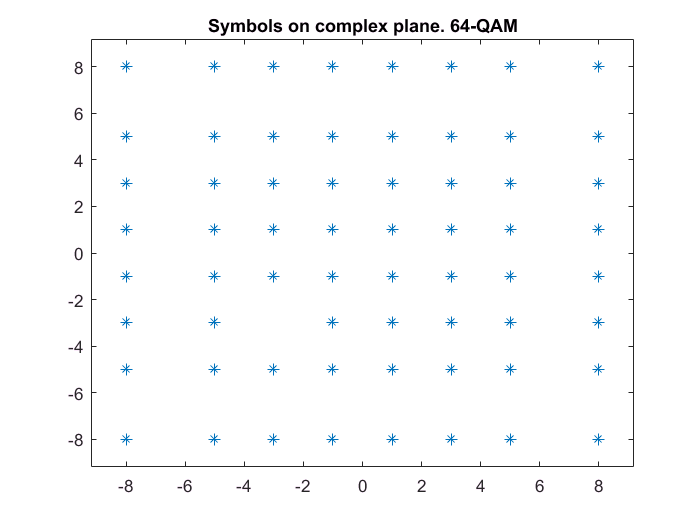

data = randi([0, 1], 1, Nbit); % Random bit-flow 0011010010
IQ_table = [-8+8*i, -5+8*i, -3+8*i, -1+8*i, 1+8*i, 3+8*i, 5+8*i, 8+8*i;
            -8+5*i, -5+5*i, -3+5*i, -1+5*i, 1+5*i, 3+5*i, 5+5*i, 8+5*i;
            -8+3*i, -5+3*i, -3+3*i, -1+3*i, 1+3*i, 3+3*i, 5+3*i, 8+3*i;
            -8+1*i, -5+1*i, -3+1*i, -1+1*i, 1+1*i, 3+1*i, 5+1*i, 8+1*i;
            -8-1*i, -5-1*i, -3-1*i, -1-1*i, 1-1*i, 3-1*i, 5-1*i, 8-1*i;
            -8-3*i, -5-3*i, -3-3*i, -1-3*i, 1-3*i, 3-3*i, 5-3*i, 8-3*i;
            -8-5*i, -5-5*i, -3-5*i, -1-5*i, 1-5*i, 3-5*i, 5-5*i, 8-5*i;
            -8-8*i, -5-8*i, -3-8*i, -1-8*i, 1-8*i, 3-8*i, 5-8*i, 8-8*i]; % Table for 4 bit on one symbol
data = reshape(data, m, Ns); 
data = bi2de(data') + 1; % Transform every binary row to decimal value
dataIQ = IQ_table(data); % Get matrix 1xNs of symbos 
                         %(that transmitted via pair bit flow)
figure         
%plot(real(dataIQ), imag(dataIQ), '*'); % Print by *
plot(real(dataIQ), imag(dataIQ), '*'); % Print by *
axis([-9.2 9.2 -9.2 9.2]);
title('Symbols on complex plane. 64-QAM');

Сигнал and Spectrum

dataIQ_long = dataIQ';
dataIQ_long = repmat(dataIQ_long, sps, 1); % SPS times make copy to next row
                                 % Get matrix sps x Ns
dataIQ_long = reshape(dataIQ_long, 1, N);  % Make one row by reading colloms
I = real(dataIQ_long);
Q = imag(dataIQ_long);
%%%%%%%%%%%%%%%%%%%%%%%%%% Signal %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure

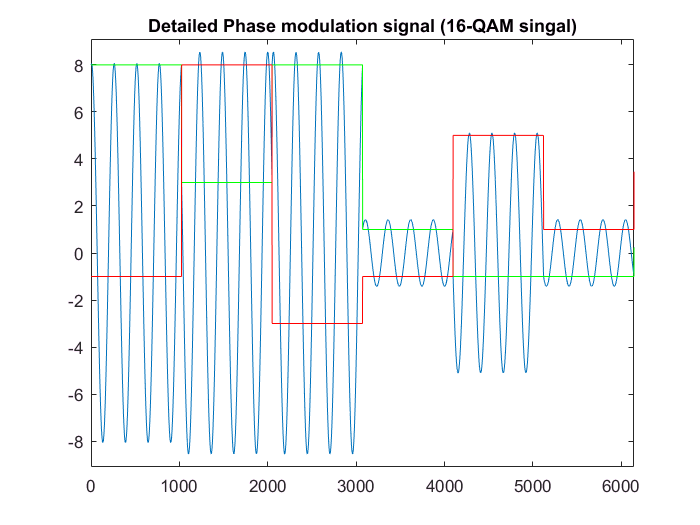

s = I.*cos(2*pi*F0*t) - Q.*sin(2*pi*F0*t);
figure
plot(s);
hold on
plot(I, 'g');
plot(Q, 'r');
axis([0 sps*6 -9.1 9.1]);
hold off
title('Detailed Phase modulation signal (16-QAM singal)');

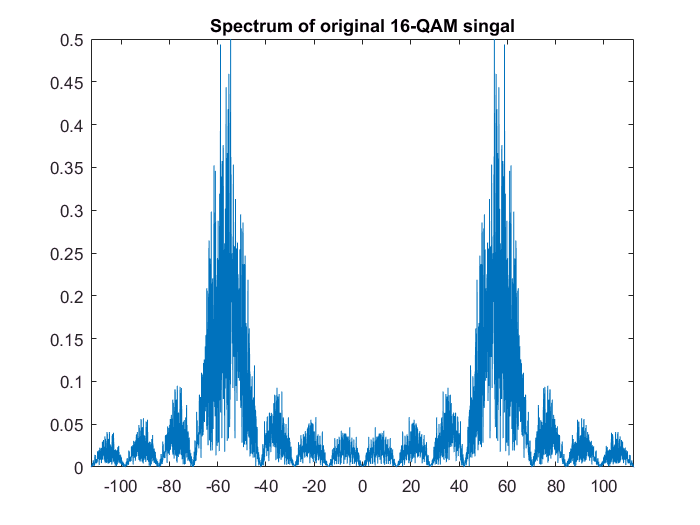

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Spectrum %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S = fftshift(fft(s))/N; % Find spectrum and shift it right part to normal place
ff = [-N/2: N/2 - 1] * Fs/N;
plot(ff, abs(S));
axis([-2*F0 2*F0 0 0.5]);
title('Spectrum of original 16-QAM singal');

Ширина спектра

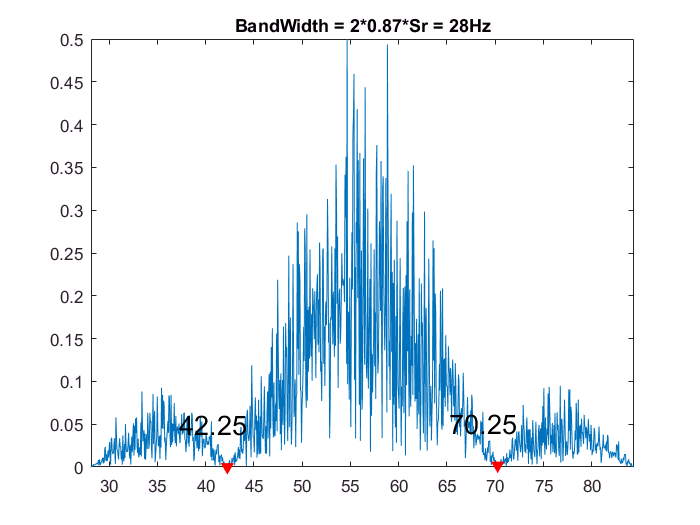

plot(ff, abs(S));
hold on
F = [F0 - 14, F0 + 14];
FreqToDot = round( ((2*F)/Fs+1)*N/2 );
FreqDot = ff( FreqToDot );
plot(F, abs(S(FreqToDot)),'rv', 'MarkerFaceColor', 'r');
celltext = cellstr(num2str(F'));
text(F-5, abs(S(FreqToDot))+0.05, celltext, 'FontSize', 16);
axis([0.5*F0 1.5*F0 0 0.5]);
title('BandWidth = 2*0.87*Sr = 28Hz');
hold off

## Прохождение через фильтр

Добавим условие, что сигнал нам важен только в некоторые моменты времени. Всего в дате сейчас 64 символа. После последующего ряда операций между символами будет вставлено 1024 нуля. То есть только каждый 1025 отчет даты важен и несет информацию. Последующая фильтрация путем произвольного поведения в промежутках между символами будет уменьшать спектр, понижая уровень боковых лепестков, но значения символов на каждом 1025 отчете будут неизменны.

dataIQ = dataIQ';
dataIQ = [dataIQ; zeros(sps-1, Ns)]; %%%%%%%%%%%%%%%%%%%%%%%%% Filtraciya
%dataIQ = repmat(dataIQ,sps,1);
dataIQ = reshape(dataIQ, 1, N);  % M

В созвездии такой даты появится точка (0,0), а I и Q будут иметь вид коротких импульсов.

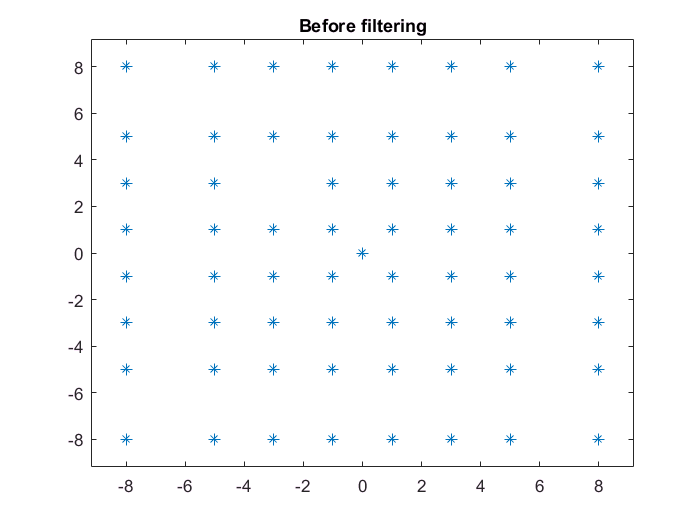

I = real(dataIQ);
Q = imag(dataIQ);
plot(I, Q, '*');
title('Before filtering');
axis([-9.2 9.2 -9.2 9.2]);

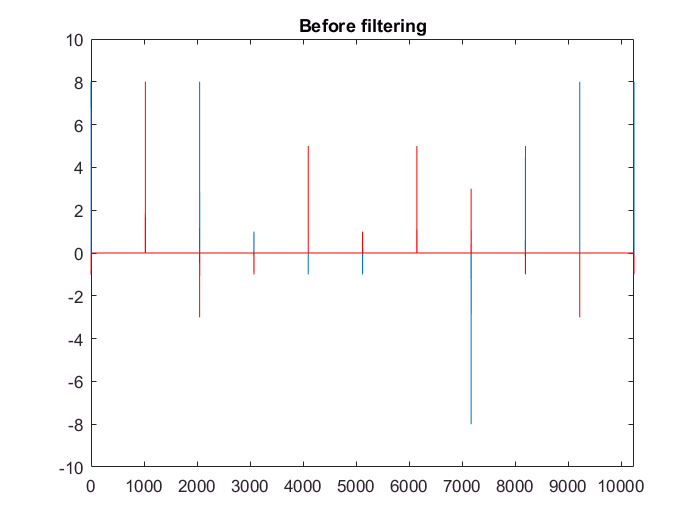

figure
plot(I);
hold on
plot(Q, 'r');
hold off
title('Before filtering');
axis([0 sps*10 -10 10]);

Создадим фильтр, импульсной характеристикой которого будет приподнятый косинус

beta = 0.4;
span = 2048;
g = rcosdesign(beta, span, sps, 'normal'); % Create filter
g = g/sum(g);                              % Normalize
g = g * sps;                               % Return power loss from filled data with zeros
figure
plot(g);
title('Plot of the pripodnyati cos')
legend('beta 0.4')
axis([1.02e6 1.08e6 -0.2 1]);

Пропустим дату через фильтр (свертка)

dataIQ_f - filtered data IQ

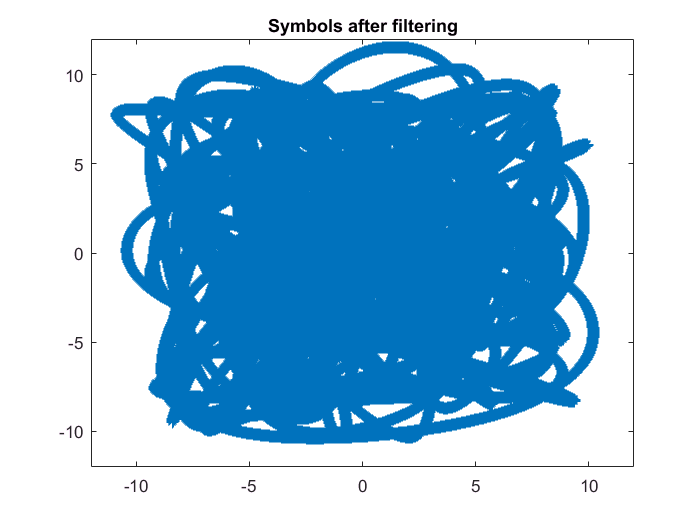

dataIQ_f = conv(dataIQ, g, 'same');
plot(real(dataIQ_f), imag(dataIQ_f), '*');
title('Symbols after filtering');
axis([-12 12 -12 12]);

Для наглядности покажу созвездие из "символов", т.е. взяв каждый sps-тый отчет выходного из фильтра сигнала

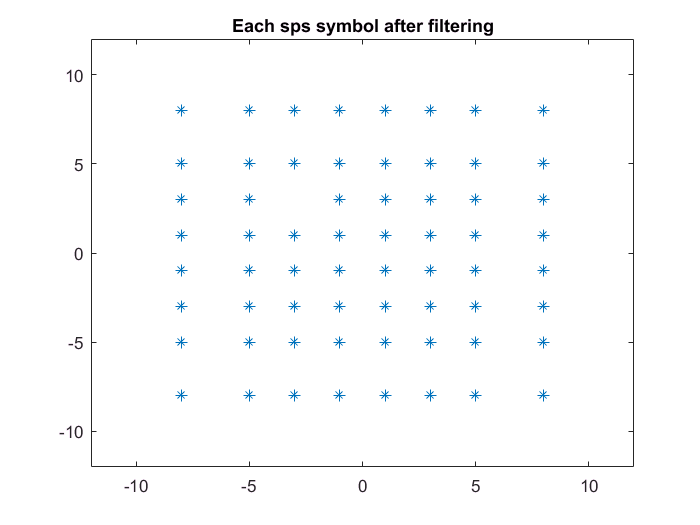

figure
plot(real(dataIQ_f(1:sps:end)), imag(dataIQ_f(1:sps:end)), '*');
title('Each sps symbol after filtering');
axis([-12 12 -12 12]);

А теперь вместе с изображением прошедшего через фильтр сигнала звездочками покажу исходную дату. Каждый 1025 отчет должен совпадать и соответствовать одной из звезд созвездия. А как видно из предыдущего графика, звезд появилось гораздо больше.

figure
plot(real(dataIQ_f));      % Filtering output I
hold on
plot(imag(dataIQ_f), 'r'); % Filtering output Q
plot([1:sps:Ns*sps],I(1:sps:end), 'b*'); % Every sps element of input I
plot([1:sps:Ns*sps],Q(1:sps:end), 'r*'); % Every sps element of input Q
hold off
title('After filtering');
axis([0 sps*10 -15 15]);

## Спектр фильрованного сигнала 16-QAM

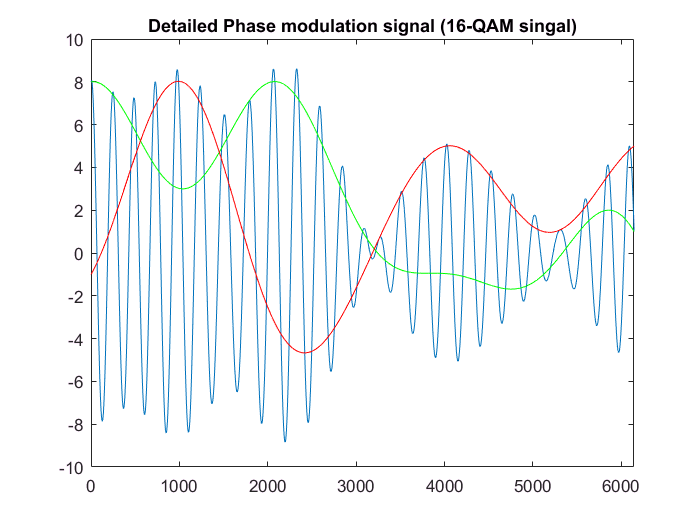

I = real(dataIQ_f);
Q = imag(dataIQ_f);
%%%%%%%%%%%%%%%%%%%%%%%%%% Signal %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
s = I.*cos(2*pi*F0*t) - Q.*sin(2*pi*F0*t);
figure
plot(s);
hold on
plot(I, 'g');
plot(Q, 'r');
axis([0 sps*6 -10 10]);
hold off
title('Detailed Phase modulation signal (16-QAM singal)');

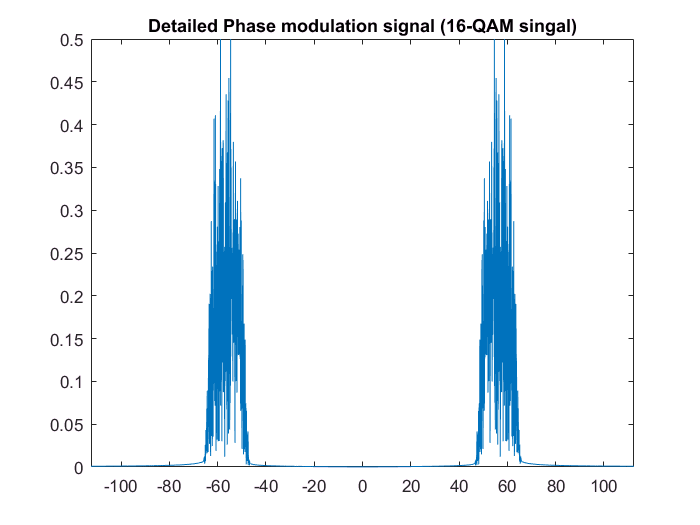

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Spectrum %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
S = fftshift(fft(s))/N; % Find spectrum and shift it right part to normal place
ff = [-N/2: N/2 - 1] * Fs/N;
plot(ff, abs(S));
axis([-2*F0 2*F0 0 0.5]);
title('Detailed Phase modulation signal (16-QAM singal)');

Спектр фильтрованного сигнала

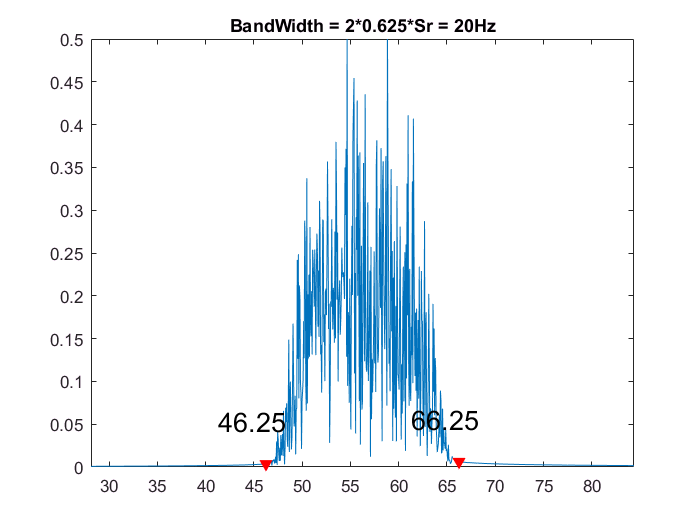

plot(ff, abs(S));
hold on
F = [F0 - 10, F0 + 10];
FreqToDot = round( ((2*F)/Fs+1)*N/2 );
FreqDot = ff( FreqToDot );
plot(F, abs(S(FreqToDot)),'rv', 'MarkerFaceColor', 'r');
celltext = cellstr(num2str(F'));
text(F-5, abs(S(FreqToDot))+0.05, celltext, 'FontSize', 16);
axis([0.5*F0 1.5*F0 0 0.5]);
title('BandWidth = 2*0.625*Sr = 20Hz');
hold off

## Выводы

- 64-QAM классная модуляция, которая может занимать ту же полосу частот, что и 16-QAM, но передавать на 2 бита за символ больше информации.

- Фильтрация приподнятым косинусом работает таким образом, что 1023 отчета из 1024 дата может принимать любые значения и только каждый 1024 отчет несет информацию о символе. Произвольными значениями между символами происходит компенсация ограничения ширины спектра и подавления боковых лепестков. С добавлением фильтра, бета которого равна 0.4, ширина спектра уменьшилась на (28-20/28) 28.5%. Из ширины 28Гц она стала 20Гц.

- Боковые лепестки при фильтрации вовсе подавились в ноль, чем значительно уменьшили влияние одного канала на соседние. А так же при полной сохранности информации спектр стал уже, чем добавил экономию на выкуп полосы занимаемых частот в эфире, если применить к радиовещанию. 

# РГР №4 - OFDM

Условия по варианту

clear all
close all
var = 9;
Br = 1000 * var; 

Время импульса (с)

T = 0.05; %1ms

Суть: С учетом гуард бэндов имеем Ncarrier несущих частот. Каждая несущая передает один символ промодулированный одним из нижеперечисленных вариантов. Тогда за время имульса T отправляются Ncarrier символов, в каждом из которых m бит. Сумма всех символов на разных несущих формируют один символ OFDM.

Br = Ncarrier*m/T = 1000*var; Если принять T = 0.050 (50ms), то для 

- QPSK m = 2. Ncarrier = Br*T/m = 225. NFFT = 225 * 10/8 = 300. (GB = 1/8 * NFFT симметрично с двух сторон )

- 16-QAM m = 4. Ncarrier = 113 (округленно). NFFT = 150 (округленно)

- 64-QAM m = 6. Ncarrier = 75. NFFT = 100.

Fs = 1024;
m = [2 4 6];
Nsymbol  = 1;
Ncarrier = Br*T./m;
NFFT = round(4/3*Ncarrier);
Ncarrier = round(Ncarrier); % round -> 113, fix -> 112
GB = round(NFFT/8);           % пo 12.5% с каждой стороны полосы частот, а не 10%. Числа красивее

Таблицы I и Q

IQtable_QPSK = [1+1*i, 1-1*i;
                -1-1*i, -1+1*i];
IQtable_16QAM = [-3+3*i, -1+3*i, 1+3*i, 3+3*i,
                -3+1*i, -1+1*i, 1+1*i, 3+1*i,
                -3-1*i, -1-1*i, 1-1*i, 3-1*i,
                -3-3*i, -1-3*i, 1-3*i, 3-3*i];
IQtable_64QAM = [-8+8*i, -5+8*i, -3+8*i, -1+8*i, 1+8*i, 3+8*i, 5+8*i, 8+8*i,
                -8+5*i, -5+5*i, -3+5*i, -1+5*i, 1+5*i, 3+5*i, 5+5*i, 8+5*i,
                -8+3*i, -5+3*i, -3+3*i, -1+3*i, 1+3*i, 3+3*i, 5+3*i, 8+3*i,
                -8+1*i, -5+1*i, -3+1*i, -1+1*i, 1+1*i, 3+1*i, 5+1*i, 8+1*i,
                -8-1*i, -5-1*i, -3-1*i, -1-1*i, 1-1*i, 3-1*i, 5-1*i, 8-1*i,
                -8-3*i, -5-3*i, -3-3*i, -1-3*i, 1-3*i, 3-3*i, 5-3*i, 8-3*i,
                -8-5*i, -5-5*i, -3-5*i, -1-5*i, 1-5*i, 3-5*i, 5-5*i, 8-5*i,
                -8-8*i, -5-8*i, -3-8*i, -1-8*i, 1-8*i, 3-8*i, 5-8*i, 8-8*i];

Nbit = m.*Ncarrier; 

От проблемы с 16QAM (при обсчетах получается 112.5 несущих) кол-во бит не одинаковое, а потому дату записіваю отдельно для каждой модуляции          

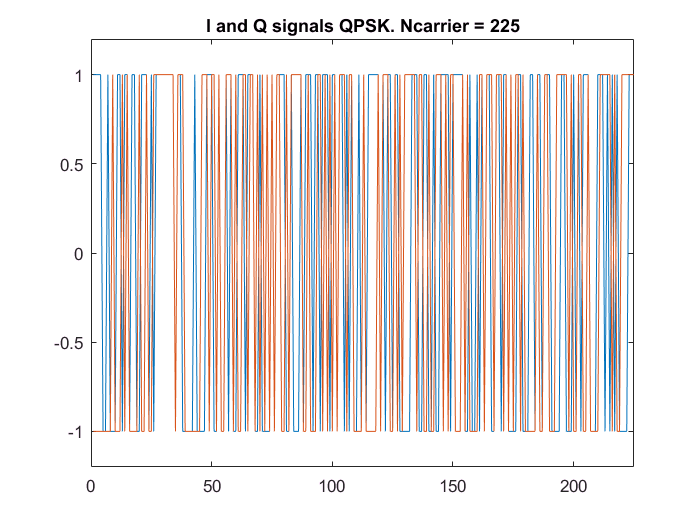

data_QPSK = randi([0, 1], 1, Nbit(1)*Nsymbol);
data_QPSK = reshape(data_QPSK, m(1), Ncarrier(1));
data_QPSK = bi2de(data_QPSK') + 1; % Transform every binary col to decimal value (1 - m+1)
dataIQ_QPSK = IQtable_QPSK(data_QPSK);

I = real(dataIQ_QPSK);
Q = imag(dataIQ_QPSK);
figure
plot(I);
hold on
plot(Q);
hold off
axis([0 Ncarrier(1) -1.2 1.2]);
title('I and Q signals QPSK. Ncarrier = 225');


data_16QAM = randi([0, 1], 1, Nbit(2)*Nsymbol);
data_16QAM = reshape(data_16QAM, m(2), Ncarrier(2));
data_16QAM = bi2de(data_16QAM') + 1; % Transform every binary col to decimal value (1 - m+1)
dataIQ_16QAM = IQtable_16QAM(data_16QAM);

I = real(dataIQ_16QAM);
Q = imag(dataIQ_16QAM);
figure
plot(I);
hold on
plot(Q);
hold off
axis([0 Ncarrier(2) -3.2 3.2]);
title('I and Q signals 16QAM. Ncarrier = 113');

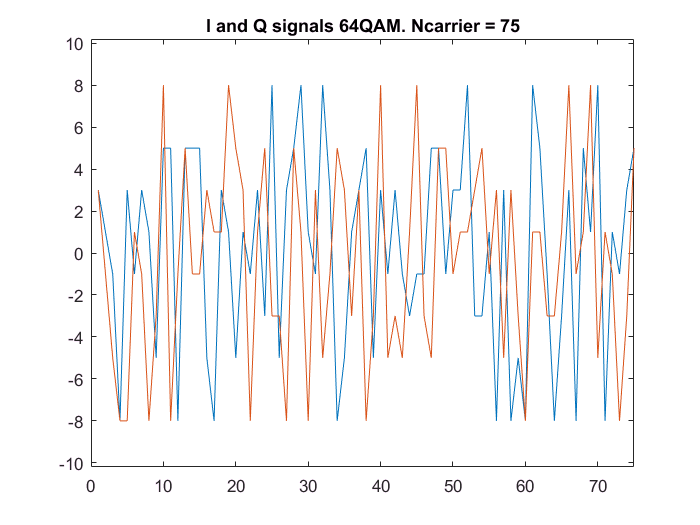


data_64QAM = randi([0, 1], 1, Nbit(3)*Nsymbol);
data_64QAM = reshape(data_64QAM, m(3), Ncarrier(3));
data_64QAM = bi2de(data_64QAM') + 1; % Transform every binary col to decimal value (1 - m+1)
dataIQ_64QAM = IQtable_64QAM(data_64QAM);

I = real(dataIQ_64QAM);
Q = imag(dataIQ_64QAM);
figure
plot(I);
hold on
plot(Q);
hold off
axis([0 Ncarrier(3) -10.2 10.2]);
title('I and Q signals 64QAM. Ncarrier = 75');

Проверка на местоположение звезд созвездия

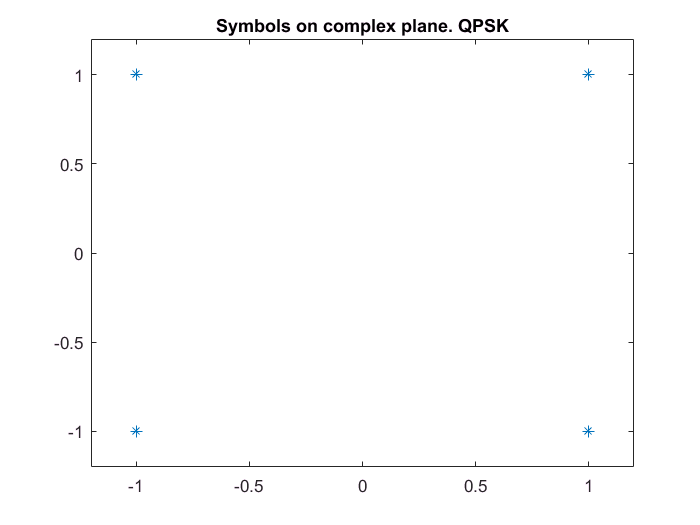


plot(real(dataIQ_QPSK), imag(dataIQ_QPSK), '*');
axis([-1.2 1.2 -1.2 1.2]);
title('Symbols on complex plane. QPSK');


plot(real(dataIQ_16QAM), imag(dataIQ_16QAM), '*');
axis([-4.2 4.2 -4.2 4.2]);
title('Symbols on complex plane. 16-QAM');

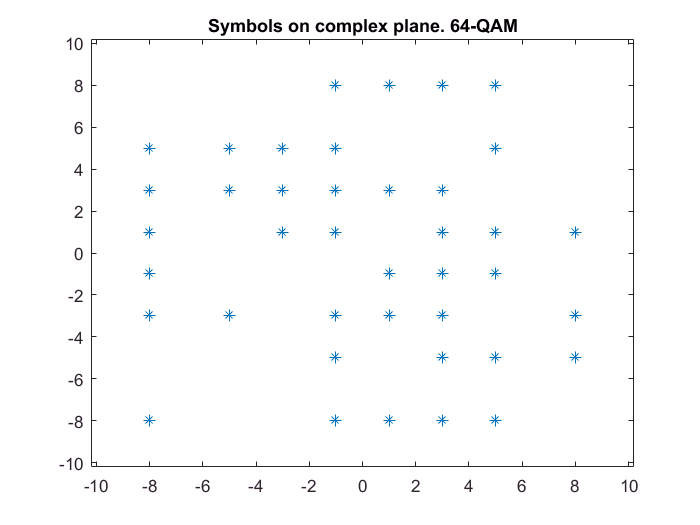


plot(real(dataIQ_64QAM), imag(dataIQ_64QAM), '*');
axis([-10.2 10.2 -10.2 10.2]);
title('Symbols on complex plane. 64-QAM');

Растягиваем сигналы во времени.

% Sr = Br*m;    %% ??
% Fs = 32*Br*m; %% ??
% sps = Fs/Sr;
% 
% 

## Формирую OFDM символ

Спектры из Ncarrier и GB по бокам.

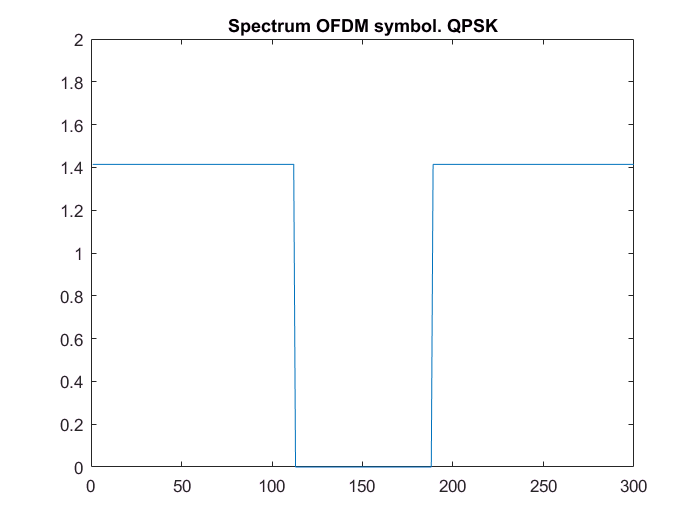

for k = 1:Nsymbol
    data_symbol_QPSK = fftshift([zeros(GB(1), 1);dataIQ_QPSK(((k-1)*Ncarrier(1)+1):k*Ncarrier(1)); zeros(GB(1), 1)]);
end
plot(abs(data_symbol_QPSK));
axis([0 NFFT(1) 0 2]);
title('Spectrum OFDM symbol. QPSK');

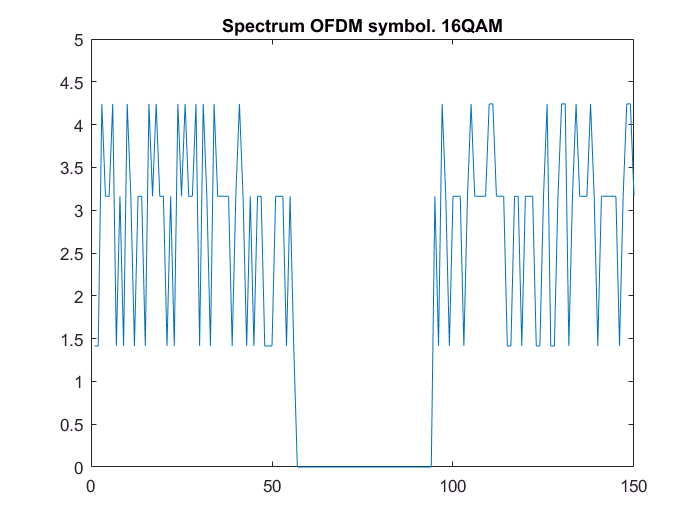


for k = 1:Nsymbol
    data_symbol_16QAM = fftshift([zeros(GB(2), 1);dataIQ_16QAM(((k-1)*Ncarrier(2)+1):k*Ncarrier(2)); zeros(GB(2), 1)]);
end
plot(abs(data_symbol_16QAM));
axis([0 NFFT(2) 0 5]);
title('Spectrum OFDM symbol. 16QAM');

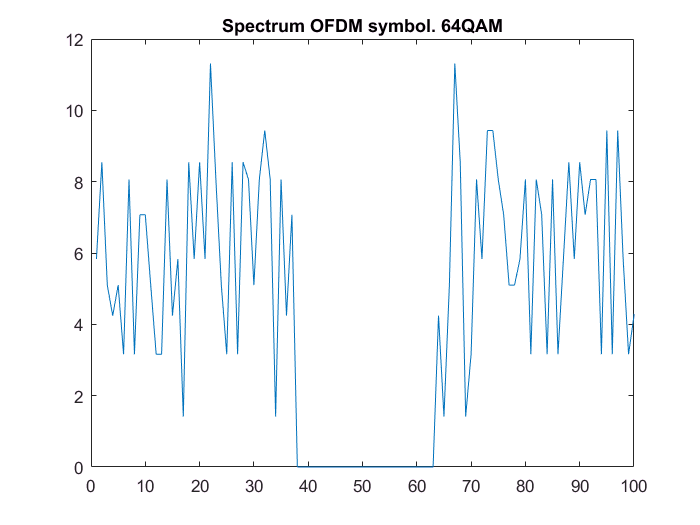


for k = 1:Nsymbol
    data_symbol_64QAM = fftshift([zeros(GB(3), 1);dataIQ_64QAM(((k-1)*Ncarrier(3)+1):k*Ncarrier(3)); zeros(GB(3), 1)]);
end
plot(abs(data_symbol_64QAM));
axis([0 NFFT(3) 0 12]);
title('Spectrum OFDM symbol. 64QAM');

Запись data_IQ(((k-1)*Ncarrier+1):k*Ncarrier) при условии Nsymbol  = 1, означает "взять первые Ncarrier символов (1-225 к примеру). Для формировки следующего символа будут взяты (226 - 550).

Получаем временные сигналы каждой модуляции. 

GI = GB; %% ?? sampels that repeat last symbol
t1 = [0:NFFT(1)+GI(1) - 1]*T/(NFFT(1)+GI(1) - 1)*1000;
data_symbol_t_QPSK = ifft(data_symbol_QPSK);
signal_time_QPSK = zeros(1, Nsymbol*(NFFT(1)+GI(1)));

t2 = [0:NFFT(2)+GI(2) - 1]*T/(NFFT(2)+GI(2) - 1)*1000;
data_symbol_t_16QAM = ifft(data_symbol_16QAM);
signal_time_16QAM = zeros(1, Nsymbol*(NFFT(2)+GI(2)));

t3 = [0:NFFT(3)+GI(3) - 1]*T/(NFFT(3)+GI(3) - 1)*1000;
data_symbol_t_64QAM = ifft(data_symbol_64QAM);
signal_time_64QAM = zeros(1, Nsymbol*(NFFT(3)+GI(3)));

Копирование последнего символа в начало

signal_time_QPSK(1:(NFFT(1)+GI(1)))  = [data_symbol_t_QPSK(end-GI(1)+1:end-1); data_symbol_t_QPSK]';
signal_time_16QAM(1:(NFFT(2)+GI(2))) = [data_symbol_t_16QAM(end-GI(2)+1:end-1); data_symbol_t_16QAM]';
signal_time_64QAM(1:(NFFT(3)+GI(3))) = [data_symbol_t_64QAM(end-GI(3)+1:end-1); data_symbol_t_64QAM]';

Отображение полученных комплексных сигналов

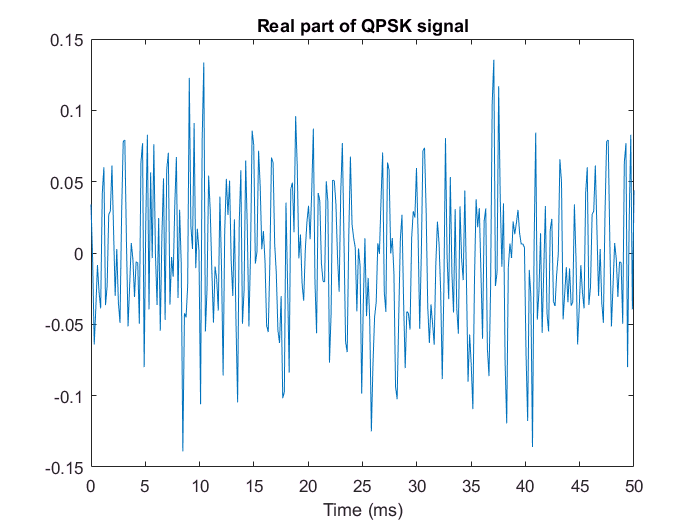

plot(t1, real(signal_time_QPSK));
title('Real part of QPSK signal');
xlabel('Time (ms)');

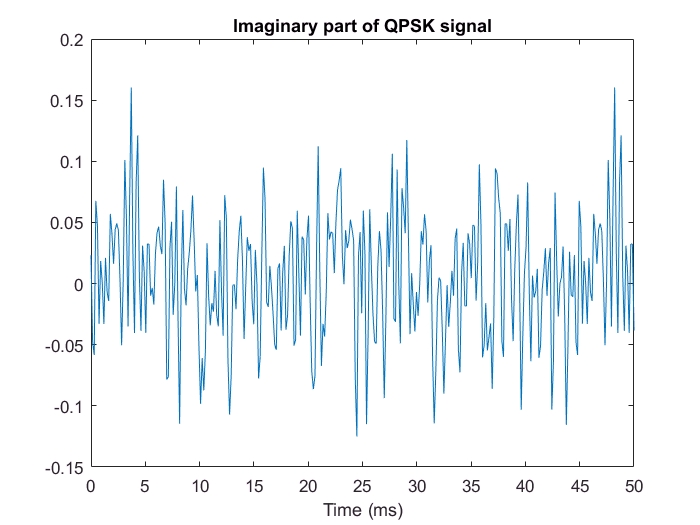

plot(t1, imag(signal_time_QPSK));
title('Imaginary part of QPSK signal');
xlabel('Time (ms)');

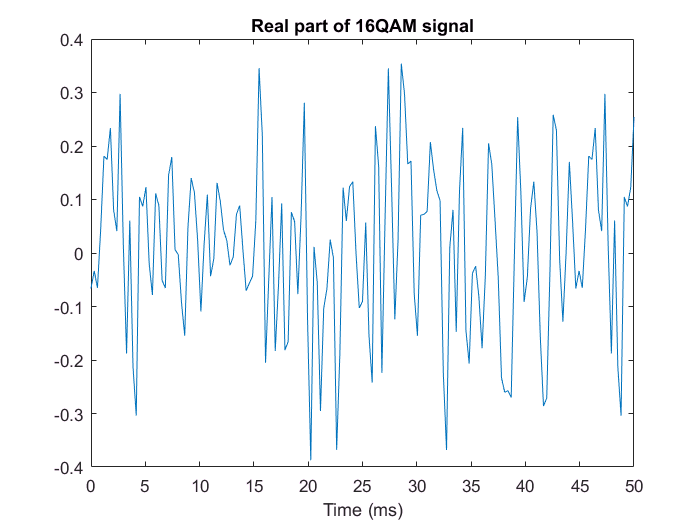


plot(t2, real(signal_time_16QAM));
title('Real part of 16QAM signal');
xlabel('Time (ms)');

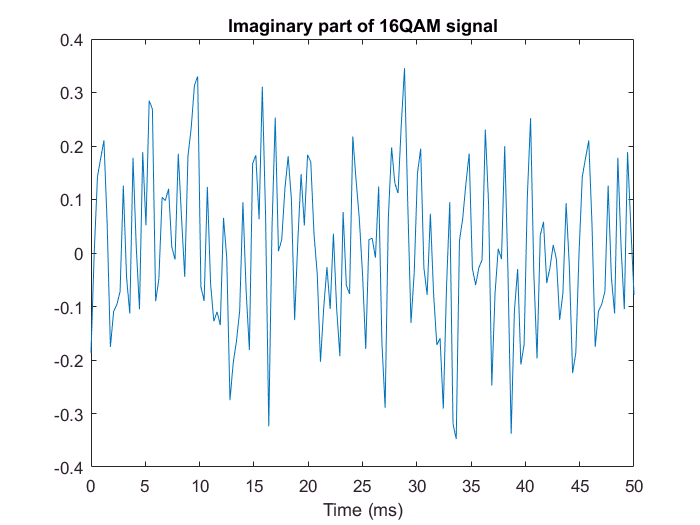

plot(t2, imag(signal_time_16QAM));
title('Imaginary part of 16QAM signal');
xlabel('Time (ms)');

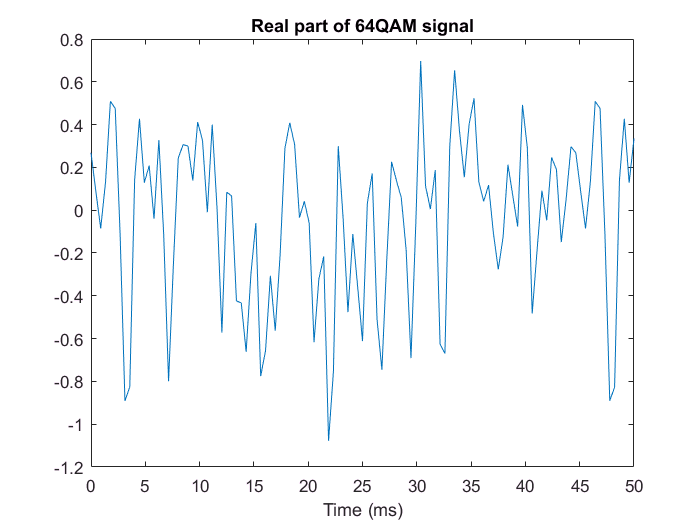


plot(t3, real(signal_time_64QAM));
title('Real part of 64QAM signal');
xlabel('Time (ms)');

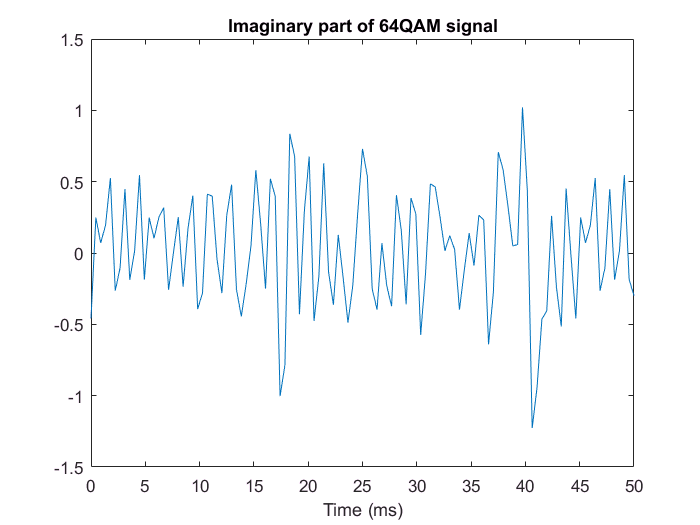

plot(t3, imag(signal_time_64QAM));
title('Imaginary part of 64QAM signal');
xlabel('Time (ms)');

## Выводы

Каждый символ, каждая звезда созвездия несет в себе одновременно кодовую информацию и информацию о сигнале, которому соответсвует код. Звезда созвездия несет в себе информацию и о фазе, и амплитуде гармонического колебания. Т. е. набор символов разной частоты (для паралельной передачи) определяет СПЕКТР передаваемого сигнала. Передаваемый сигнал будет состоять из гармонических колебаний с амплитудой и фазой в соответствии с символом.

Из таких соображений были построены вышеуказанные спектры для сигналов разной модуляции. 

- Как видно при модуляции QPSK амплитуда у всех одинаковая, а фазовую характеристику я не изображал. Звезды созвездия лежат на единичном круге, т.е. отличаются только фазой, значит спектр сходится с теорией.

- Для спектра 16-QAM модуляции видно 3 уровня амплитуды. Они соответствуют трем разноотдаленным квадратам созвездий. (+-1 +-1), (+-1/3 +-3/1), (+-3 +-3).

- Аналогично для спектра 64-QAM модуляции будет больше разных уровней амплитуды, от чего ширина спектра будет меньшей

Сигнал каждой модуляции занимает столько несущих частот:

- QPSK -     300 несущих (225 несут информацию)

- 16-CAM - 150 несущих (113 несут информацию)

- 64-CAM - 100 несущих (75 несут информацию)

Ширина спектра модулированного сигнала зависит от Sr -symbol rate. Как видно из спектрограмм каждого модулированного сигнала ширина спектра - это приблизительно удвоенный Sr. Если принять скорость передачи символов для сигналов своей модуляции одинаковой, то и ширина спектра, что QPSK, так и 16- 64-QAM будут одинаковой. К примеру возьму Sr = 900, как в РГР №2. Тогда Ширина спектра занимаемая OFDM группой сигналов определяется как ( NFFT * SpectrumWidth / 2 ) 

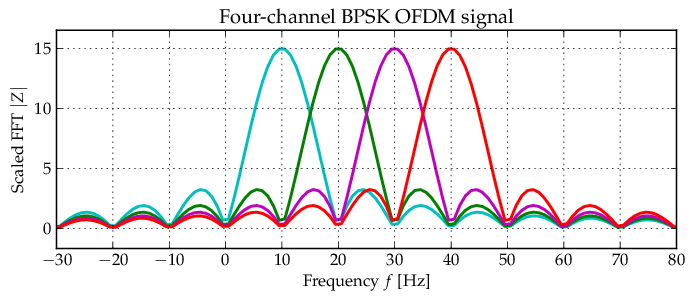

Если учесть, что фильтрованый каждая модуляция занимает SpectrumWirth = 1800;

- QPSK -     270 kHz 

- 16-QAM - 135 kHz

- 64-QAM -  90 kHz

Из этих выводов можно заключить, что

- Модуляция 64-QAM несет больше всего информации с одного гармонического колебания, а значит для передачи того же объема данных за тот же промежуток времени сигнал с такой модуляцией займет минимальную полосу частот, по сравнению с вышенаписанными модуляциями.